# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.1 优雅的绘图颜色

#### 2.1.1 颜色模板

**准备了 60 套颜色模板，每套模板 6 种颜色**

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

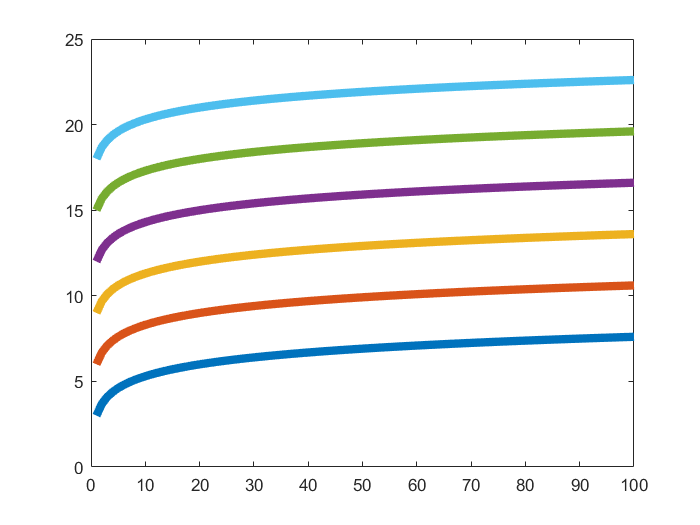

clear;clc;close all;
% 先看一下默认颜色，其实还是很漂亮的颜色
figure;
DemoPlot();

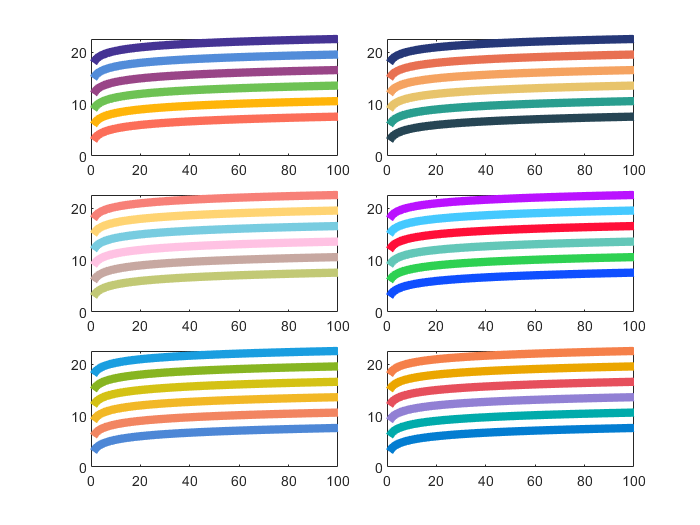

% 获取所有的颜色模板和颜色
[all_themes, all_colors] = GetColors();
figure;
% 类似subplot
tiledlayout(3, 2, 'TileSpacing', 'compact');
for j = 1 : 6
    nexttile;
    DemoPlot();
    % 这里修改一下颜色顺序colororder即可
    set(gca, 'colororder', all_themes{j});
end

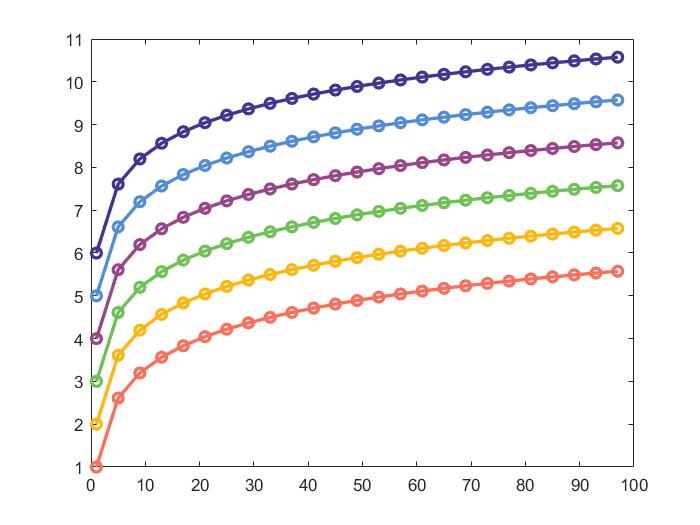

% 或者指定颜色
figure;
x = 1:4:100;
y = log(x);
for i = 1:6
    plot(x, y + i, 'o-', 'Color', all_colors(i, :), 'LineWidth', 2);
    hold on
end
hold off

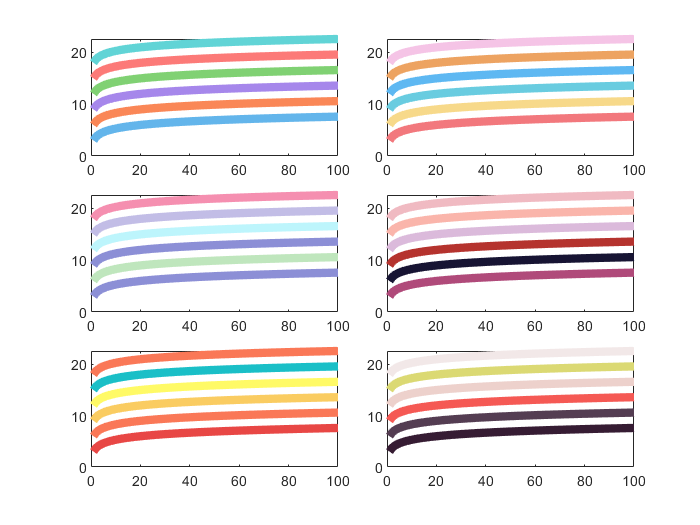

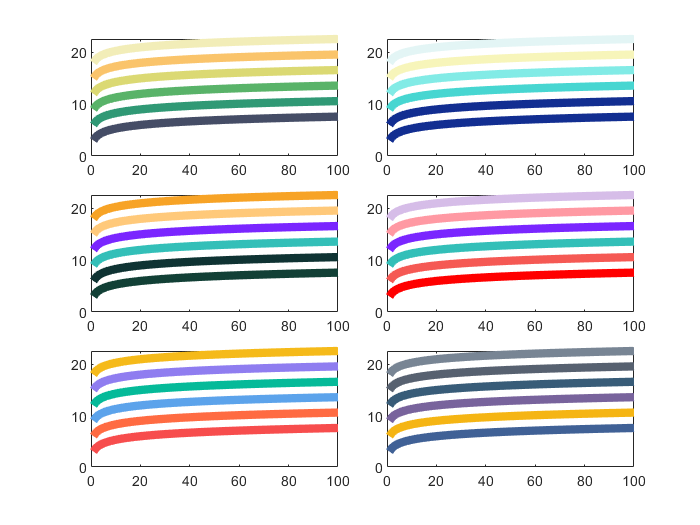

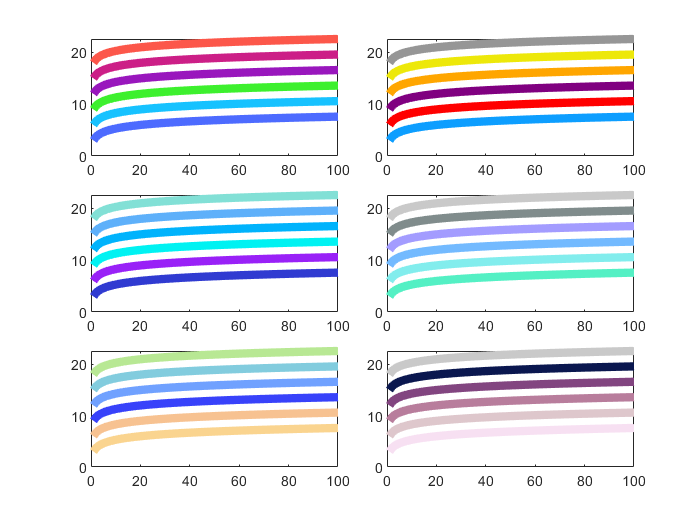

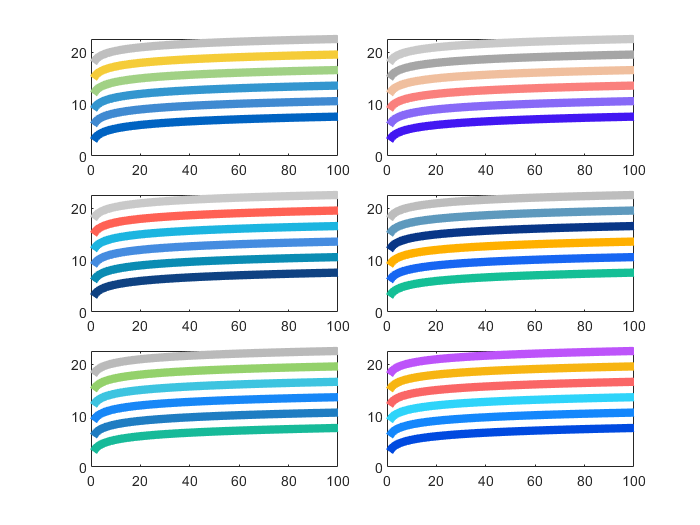

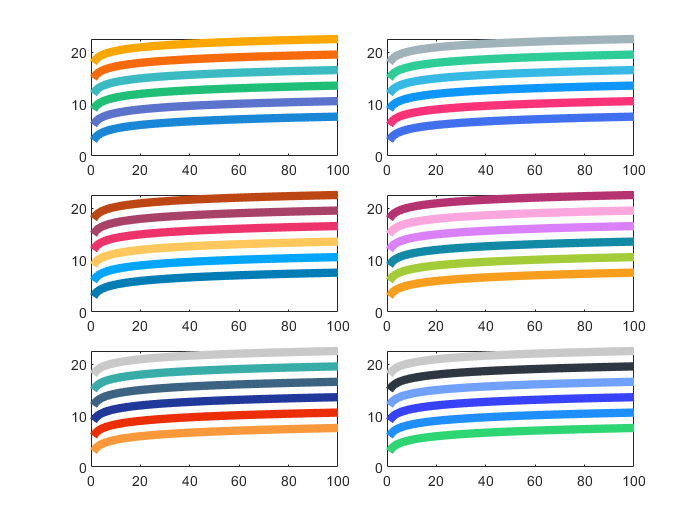

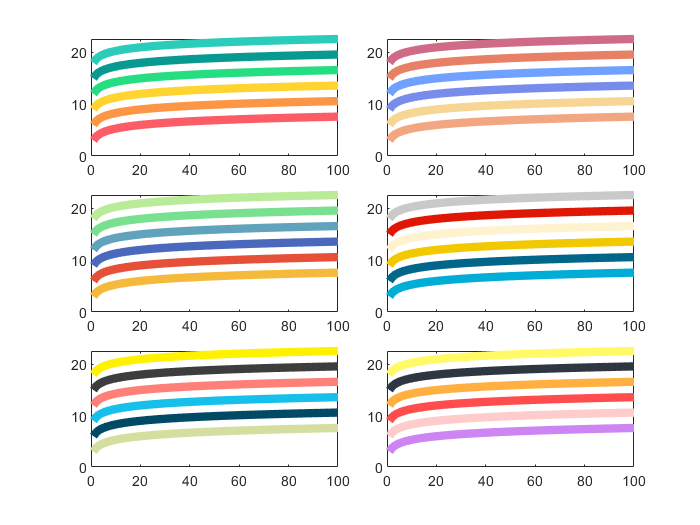

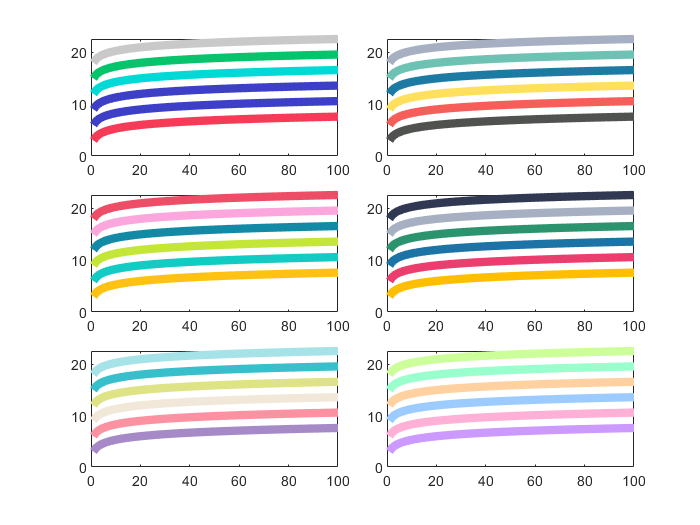

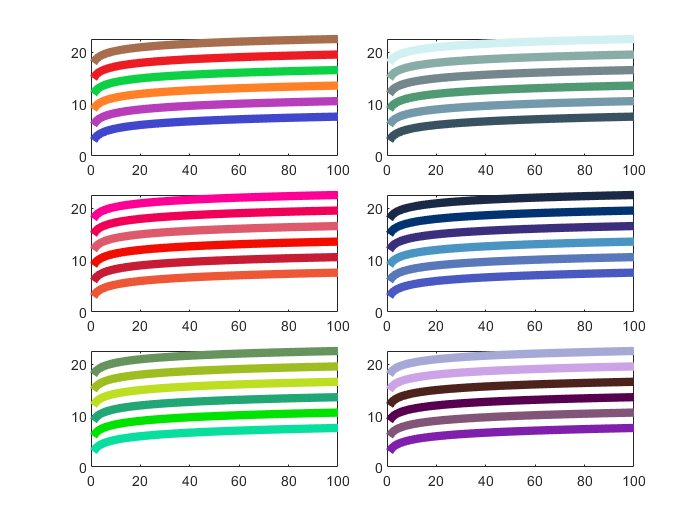

% 再欣赏一下所有颜色
for i = 1:6:length(all_themes)
    figure;
    % 和 subplot 类似
    tiledlayout(3, 2, 'TileSpacing', 'compact');
    for j = 1:6
        nexttile
        DemoPlot();
        set(gca, 'colororder', all_themes{i+j-1});
    end
end

function DemoPlot()
% 定义一个简单的绘图函数
x = 1:100;
y = log(x);
for i = 1:6
    plot(x, y + 3*i, 'LineWidth', 5);
    hold on
end
hold off
end